fname = '4x_4.bag';
% Create a bag file object with the file name by omitting the
% semicolon this displays some information about the bag file
bag = rosbag(fname);
  
% Display a list of the topics and message types in the bag file
bag.AvailableTopics;
 
%% Create a time series of the Odometry data
% Retrieve the messages as a cell array
geom_msgs = select(bag,'Topic','/rabbit');
 
% Create a timeseries object of the subset of message fields we are interested in
geom_ts = timeseries(geom_msgs,'Point.X','Point.Y');

% Retrieve the messages as a cell array
odom_msgs = select(bag,'Topic','/cora1/cora/sensors/p3d');
 
% Create a timeseries object of the subset of message fields we are interested in
odom_ts = timeseries(odom_msgs,'Pose.Pose.Position.X','Pose.Pose.Position.Y');

% Retrieve the messages as a cell array
odom2_msgs = select(bag,'Topic','/cora2/cora/sensors/p3d');
 
% Create a timeseries object of the subset of message fields we are interested in
odom2_ts = timeseries(odom2_msgs,'Pose.Pose.Position.X','Pose.Pose.Position.Y');

% Retrieve the messages as a cell array
odom3_msgs = select(bag,'Topic','/cora3/cora/sensors/p3d');
 
% Create a timeseries object of the subset of message fields we are interested in
odom3_ts = timeseries(odom3_msgs,'Pose.Pose.Position.X','Pose.Pose.Position.Y');

% Retrieve the messages as a cell array
odom4_msgs = select(bag,'Topic','/cora4/cora/sensors/p3d');
 
% Create a timeseries object of the subset of message fields we are interested in
odom4_ts = timeseries(odom4_msgs,'Pose.Pose.Position.X','Pose.Pose.Position.Y');

%% Plot X/Y Positions
figure(1); clf();
% Plot the Data index
plot(geom_ts.Data(:,1),geom_ts.Data(:,2))
hold on
% plot(odom_ts.Data(:,1),odom_ts.Data(:,2),'r')
% plot(odom2_ts.Data(:,1),odom2_ts.Data(:,2),'g')
plot(odom3_ts.Data(:,1),odom3_ts.Data(:,2),'k')
plot(odom4_ts.Data(:,1),odom4_ts.Data(:,2),'m')
xlabel('X-Position [m]')
ylabel('Y-Postition [m]')
legend('Rabbit','Cora1','Cora2','Cora3','Cora4')

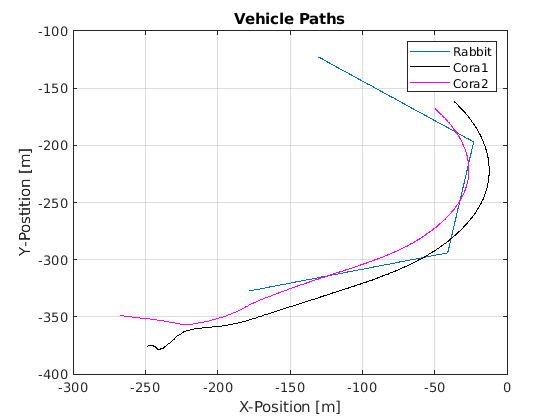

grid on
title('Vehicle Paths')

% xlim([0 60])
% ylim([-380 -330])

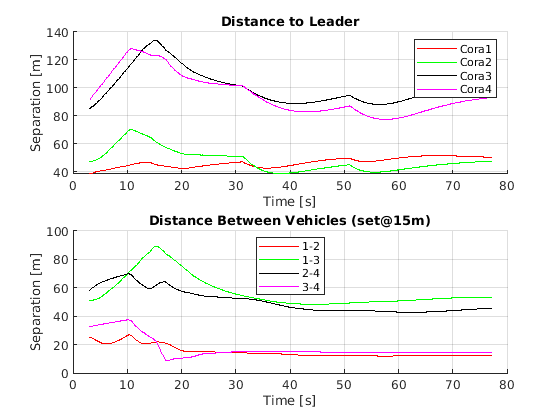

% plot distances
Ldist1 = sqrt((odom_ts.Data(:,1)-geom_ts.Data(:,1)).^2 + (odom_ts.Data(:,2)-geom_ts.Data(:,2)).^2);
Ldist2 = sqrt((odom2_ts.Data(:,1)-geom_ts.Data(:,1)).^2 + (odom2_ts.Data(:,2)-geom_ts.Data(:,2)).^2);
Ldist3 = sqrt((odom3_ts.Data(:,1)-geom_ts.Data(:,1)).^2 + (odom3_ts.Data(:,2)-geom_ts.Data(:,2)).^2);
Ldist4 = sqrt((odom4_ts.Data(:,1)-geom_ts.Data(:,1)).^2 + (odom4_ts.Data(:,2)-geom_ts.Data(:,2)).^2);

dist12 = sqrt((odom_ts.Data(:,1)-odom2_ts.Data(:,1)).^2 + (odom_ts.Data(:,2)-odom2_ts.Data(:,2)).^2);
dist13 = sqrt((odom_ts.Data(:,1)-odom3_ts.Data(:,1)).^2 + (odom_ts.Data(:,2)-odom3_ts.Data(:,2)).^2);
dist24 = sqrt((odom2_ts.Data(:,1)-odom4_ts.Data(:,1)).^2 + (odom2_ts.Data(:,2)-odom4_ts.Data(:,2)).^2);
dist34 = sqrt((odom4_ts.Data(:,1)-odom3_ts.Data(:,1)).^2 + (odom4_ts.Data(:,2)-odom3_ts.Data(:,2)).^2);

figure (2); clf()
subplot(2,1,1)
hold on
plot(odom_ts.Time(:),Ldist1,'r')
plot(odom2_ts.Time(:),Ldist2,'g')
plot(odom3_ts.Time(:),Ldist3,'k')
plot(odom4_ts.Time(:),Ldist4,'m')
hold off
grid on
title('Distance to Leader')
xlabel('Time [s]')
ylabel('Separation [m]')
% xlim([10 120])
legend('Cora1','Cora2','Cora3','Cora4')

subplot(2,1,2)
hold on
plot(geom_ts.Time(:),dist12,'r')
plot(geom_ts.Time(:),dist13,'g')
plot(geom_ts.Time(:),dist24,'k')
plot(geom_ts.Time(:),dist34,'m')
grid on
title('Distance Between Vehicles (set@15m)')
xlabel('Time [s]')
ylabel('Separation [m]')
% ylim([18 22])
legend('1-2','1-3','2-4','3-4','Location','best')